## Week 2 Part 1 - Matlab Class

## Dave Hill

Today, we will look at elements, vectors, matrices

clear all
close all

## Single vs. Double Precision

We are going to begin by talking about variables and variable types. Let us start by looking at a single variable

format long
e = exp(1)

e =    2.718281828459046


format
e = exp(1)

e = 2.7183

size(e)

ans =      1     1


whos

  Name      Size            Bytes  Class     Attributes

  ans       1x2                16  double              
  e         1x1                 8  double              



Note, during the 'whos' command, that it is shown as double. What does this mean? What is single precision? A single precision floating point number uses 32 bits, which are numbered 0 to 31. A zero in the 31st means positive a 1 in that bit means negative. The exponent uses 8 bits (bits 23 to 30) and is a signed integer running from -128 to 127. The fraction, or significand, uses bits 0 to 22. Double precision? Uses 64 bits. Many more decimal digits. So, why not use double for everything? Slower. And, in terms of saving data, much, much more storage required.

## Integers

There are also many kinds of integers, in addition to floating point numbers

int8(255)       %runs from -128 to 127

ans = int8
127

%clips integer because it doesn't go that high
uint8(255)      %runs from 0 to 255 

ans = uint8
255

uint8(-255)     %runs from 0 to 255

ans = uint8
0

%clips integer because it doesn't go that low, be aware of type of
%information you're working with, helps to save storage 

So, what happened there? 2^8 is equal to 256. So, an eight bit integer has 256 possible values, which run from 0 to 255 in the 'unsigned' (always positive) case and -128 to 127 in the 'signed' (+ / -) case.

Things get weirder below.

t=1

t = 1

isinteger(t)

ans = logical
   0


t2=int8(t)

t2 = int8
1

isinteger(t2)

ans = logical
   1


By default, Matlab thinks everything is double precision. Thus the 'isinteger' function operating on t yields 0. This is a 'boolean' function (either 1 for true or 0 for false). We FORCE t to be an integer with the int8 function, which is why 'isinteger' returns 'true' (1) for t2.

Matlab default = double precision, therefore to use something else you must convert it into int8 or something else.

## Matrix Basics

clear all

Note that I use clear a lot, just to clean up the workspace. Let us now talk about a matrix. Note: a single element (a scalar) is treated as a 1 x 1 matrix. Matlab matrices are 'ordered' as:

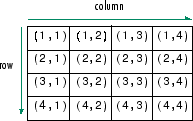

In other words, row then column, with indexing starting at '1'.

home
A = rand(5,3) %randome number

A =     0.5896    0.8482    0.7615
    0.3558    0.8810    0.7742
    0.1520    0.7436    0.1154
    0.3046    0.2626    0.4353
    0.0220    0.9311    0.0007


size(A) %output gives you rows by columns 

ans =      5     3


If we think of this as an observational data matrix (from an experiment), we could think about the columns representing various variables that we observe / measure, and the rows as being different observation times (or samples). We can get the number of samples and variables from the 'size' command.

numberSamples = size(A,1) %1 - rows

numberSamples = 5

numberVariables = size(A,2) %2 - columns

numberVariables = 3

So, each time, we are asking for the 'size' of a given dimension. We can do both at the same time, if we want!

[numberSamples numberVariables] = size(A)

numberSamples = 5

numberVariables = 3

Now, the next thing to talk about is 'indexing.' How do we access the value in a particular location of a matrix? Say we wanted to get the bottom right element. Since we just determined the size of the matrix, we can use those variables to get the bottom right...

A(numberSamples, numberVariables)   %This is a way of getting the bottom right corner

ans = 7.2364e-04

%gives you the value at A(5, 3)

Ok, well, there are a MILLION different ways of doing this. Let's look at the matrix again.

A

A =     0.5896    0.8482    0.7615
    0.3558    0.8810    0.7742
    0.1520    0.7436    0.1154
    0.3046    0.2626    0.4353
    0.0220    0.9311    0.0007


The 'end' command is really useful. It identifes the 'end' (duh...) of a vector, or of a row / column.

A(end,end)  %this is another way of getting the bottom right corner

ans = 7.2364e-04

Now, remember that punctuation is HUGE in matlab. The colon has so many uses. In one context it means 'all.' So, we can use the colon to grab 'all' elements in a given row or column. For example, let us grab 'all' in the last (using 'end') column.

A(:,end)    %here, the colon means 'all.' So, it basically means 'all rows' of the 'end' (or last) column

ans =     0.7615
    0.7742
    0.1154
    0.4353
    0.0007


And, let's grab all elements in the bottom row

A(end,:)    %here, we get the bottom row

ans =     0.0220    0.9311    0.0007


## Much more on matrix indexing...also called 'addressing'

Let's start fresh with an 8 x 3 matrix.

clear all
A=rand(8,3)

A =     0.0835    0.3160    0.9656
    0.4955    0.8828    0.1808
    0.5902    0.1959    0.3540
    0.0468    0.9124    0.5059
    0.0624    0.0915    0.8376
    0.2325    0.0140    0.5324
    0.8855    0.5527    0.7743
    0.0187    0.8167    0.4476


We can grab any elements that we want, directly, by using numbers to access certain locations.

A(1,3)

ans = 0.9656

A(3,2)

ans = 0.1959

%A(10,10)

So, hold one, what went wrong with that last attempt? As you will see, the execution of this 'section' crashed. So, put a comment symbol (%) in front of that final line and re-run this section.

Next, let's look at some non-intuitive aspects of addressing...Recall that we can easily get the bottom, right element with 'end.'

A

A =     0.0835    0.3160    0.9656
    0.4955    0.8828    0.1808
    0.5902    0.1959    0.3540
    0.0468    0.9124    0.5059
    0.0624    0.0915    0.8376
    0.2325    0.0140    0.5324
    0.8855    0.5527    0.7743
    0.0187    0.8167    0.4476


A(end,end)

ans = 0.4476

And, let us again obtain information on the 'size' of A

junk = size(A)

junk =      8     3


So, those numbers stored in 'junk' look like the location of the bottom right corner. Let's try to access that element with those values.

A(junk)

ans =     0.0187    0.5902


So, this is a curious result. The variable 'junk' is NOT a 'row, column' pair that can be used to index into a matrix. Rather, it is a vector containinig two values (8, and 3). So, Matlab simply thinks that you want the 8th and the 3rd element of the matrix. And, Matlab has another way of thinking about elements in matrices...For this 8x3 matrix, we have 24 elements, and Matlab is happy to go grab any of those. Matlab will count down the first column, 1 --> 8, and then the second column, 9 -->16, and so on.

So, to get that bottom  right value, we could try another way, using the elements of the vector 'junk' as a row, column pair.

A

A =     0.0835    0.3160    0.9656
    0.4955    0.8828    0.1808
    0.5902    0.1959    0.3540
    0.0468    0.9124    0.5059
    0.0624    0.0915    0.8376
    0.2325    0.0140    0.5324
    0.8855    0.5527    0.7743
    0.0187    0.8167    0.4476


A(junk(1),junk(2))

ans = 0.4476

That worked! Another thing we can do is to cleverly use the 'prod' (product) function operating on the 'size' vector describing A.

A(prod(size(A)))

ans = 0.4476

## Switching Between Indices and Subscripts

The sub2ind and ind2sub functions are useful ways of switching back and forth between these two different ways of addressing matrix elements. Let's look at the 12th element of A

A

A =     0.0835    0.3160    0.9656
    0.4955    0.8828    0.1808
    0.5902    0.1959    0.3540
    0.0468    0.9124    0.5059
    0.0624    0.0915    0.8376
    0.2325    0.0140    0.5324
    0.8855    0.5527    0.7743
    0.0187    0.8167    0.4476


A(12)

ans = 0.9124

So, say we want to know the row / column subscript values of the 12th element

Use this when you want to get the r anc c values for the 12th element of matriz A with size = size(A)

[r c] = ind2sub(size(A),12) %r c are the row / column corresponding to element 12.

r = 4

c = 2

## Subsetting Matrices

Let's now try a much bigger matrix (note that I use a semi-colon to suppress output of it). Remember we can think of columns as being individual variables that have been measured / observed and rows as being individual sample times.

A = rand(300,100);
size(A)

ans =    300   100


Now, say we want to extract only a few variables (columns); say 1, 15, 25, and 40. Define a vector of column numbers to 'keep.'

keep = [1 15 25 40] %values = which COLUMNS you want to keep

keep =      1    15    25    40


A_keep = A(:,keep);  %again, the colon means all rows in the requested columns                    
size(A_keep)

ans =    300     4


In looking at the size of the reduced matrix, we see that we indeed managed to extract 4 complete columns. What if we wanted to keep every 5th column? Like column 1, 6, 11, 16, etc.? It would be annoying to type that all out. So, create a vector with two colons

keep = 1:5:100 %or you could use 1:5:end, start at 1, every 5. end at 100 or end 

keep =      1     6    11    16    21    26    31    36    41    46    51    56    61    66    71    76    81    86    91    96


A_keep = A(:,keep);
size(A_keep)

ans =    300    20


%You can do the exact same things in terms of extracting selected rows

## More Subsetting Matrices!

What if we wanted to extract a list of particular elements, and not just particular rows or columns. Let's start by constructing a 5x5 matrix

clear all
A = rand(5, 5)           

A =     0.2642    0.9392    0.2612    0.2255    0.6504
    0.8565    0.3418    0.4716    0.6938    0.2425
    0.5657    0.3070    0.7716    0.6211    0.5718
    0.7703    0.3083    0.9448    0.2169    0.4290
    0.0263    0.8040    0.2716    0.6524    0.2816


Next, assume that we have a list of row and column locations of elements that interest us

rowList = [1 3 5]

rowList =      1     3     5


colList = [2 3 4]

colList =      2     3     4


In other words, we want the element in row 1 / column 2, in row 3 / column 3 and so on (a total of THREE elements, in this example). Let's try the following

A_keep = A(rowList, colList)  

A_keep =     0.9392    0.2612    0.2255
    0.3070    0.7716    0.6211
    0.8040    0.2716    0.6524


Nope, total fail. Instead of picking off three elements, for the first row number, we get all the selected column elements. Then for the second row number, we get all the selected column elements, and so on...The RIGHT way to do this is to first convert the subscripts into indices with sub2ind, and then simply go into the matrix to find those elements.

ind = sub2ind(size(A), rowList, colList)  

ind =      6    13    20


Remember, Matlab will count elements down the first column (elements 1 --> 5), then the second column (elements 6 --> 10), and so on.

A_keep2 = A(ind)               % grab just the required elements

A_keep2 =     0.9392    0.7716    0.6524


## Logical Indexing

Remember that Matlab has 'boolean' functions that return a 0 or 1, depending on if something is true or false. We can make use of this concept to extract matrix elements depending on whether or not they satisfy some criterion. Let's make up a matrix of numbers, again with columns representing variables and rows representing sample or observation numbers.

clear
A = rand(10,5)

A =     0.1815    0.4775    0.1557    0.6107    0.3732
    0.5367    0.6267    0.7583    0.8219    0.3029
    0.9714    0.0216    0.7081    0.1393    0.1067
    0.9884    0.2253    0.1252    0.6885    0.6379
    0.2952    0.6057    0.8827    0.3215    0.9039
    0.6606    0.6661    0.1780    0.0202    0.2725
    0.5757    0.2657    0.8220    0.6952    0.7560
    0.7269    0.7652    0.7427    0.4445    0.2964
    0.3943    0.0869    0.3307    0.7966    0.4467
    0.5804    0.7132    0.5985    0.9589    0.7328


Now, let's say that we want to look at only the samples (rows) in which variable (column) number 3 is greater than 0.5. We can locate those rows with the find command

I=find(A(:,3)>0.5)  % notice this is a column vector, all indicies of rows of col 3 where value > 0.5

I =      2
     3
     5
     7
     8
    10


So, now, the I variable contains those row numbers. Let's subset our matrix to keep only those rows (and we'll keep all columns in those rows)

A_keep = A(I,:) %I from above = row number where the value is > 0.5

A_keep =     0.5367    0.6267    0.7583    0.8219    0.3029
    0.9714    0.0216    0.7081    0.1393    0.1067
    0.2952    0.6057    0.8827    0.3215    0.9039
    0.5757    0.2657    0.8220    0.6952    0.7560
    0.7269    0.7652    0.7427    0.4445    0.2964
    0.5804    0.7132    0.5985    0.9589    0.7328


You can do this in a single step!

A_keep=A(find(A(:,3)>0.5),:) %in al roiws of col 3, what indicies are > 0.5 and what are the rows

A_keep =     0.5367    0.6267    0.7583    0.8219    0.3029
    0.9714    0.0216    0.7081    0.1393    0.1067
    0.2952    0.6057    0.8827    0.3215    0.9039
    0.5757    0.2657    0.8220    0.6952    0.7560
    0.7269    0.7652    0.7427    0.4445    0.2964
    0.5804    0.7132    0.5985    0.9589    0.7328


And, you can do this even without the find command!

A_keep=A((A(:,3)>0.5),:) %only keeps the rows where the col 3 value is greater than 0.5

A_keep =     0.5367    0.6267    0.7583    0.8219    0.3029
    0.9714    0.0216    0.7081    0.1393    0.1067
    0.2952    0.6057    0.8827    0.3215    0.9039
    0.5757    0.2657    0.8220    0.6952    0.7560
    0.7269    0.7652    0.7427    0.4445    0.2964
    0.5804    0.7132    0.5985    0.9589    0.7328


We can get fancier by combining multiple criteria. For example, let's keep the rows where variable (column) 3 is greater than 0.3 and less than 0.7

A

A =     0.1815    0.4775    0.1557    0.6107    0.3732
    0.5367    0.6267    0.7583    0.8219    0.3029
    0.9714    0.0216    0.7081    0.1393    0.1067
    0.9884    0.2253    0.1252    0.6885    0.6379
    0.2952    0.6057    0.8827    0.3215    0.9039
    0.6606    0.6661    0.1780    0.0202    0.2725
    0.5757    0.2657    0.8220    0.6952    0.7560
    0.7269    0.7652    0.7427    0.4445    0.2964
    0.3943    0.0869    0.3307    0.7966    0.4467
    0.5804    0.7132    0.5985    0.9589    0.7328


keepVector = find(A(:,3) > 0.3 & A(:,3) <= .7)  %mulitple criteria

keepVector =      9
    10


A_keep = A(keepVector,:)

A_keep =     0.3943    0.0869    0.3307    0.7966    0.4467
    0.5804    0.7132    0.5985    0.9589    0.7328


## Concatenation

Concatenation is all about taking matrices as building blocks and putting them together to make larger matrices. Let's start by creating three matrices of different sizes

clear all
data1 = rand(5,4)

data1 =     0.3805    0.4995    0.7715    0.2079
    0.4960    0.5970    0.9562    0.2267
    0.6190    0.8174    0.8362    0.3579
    0.9164    0.9857    0.3947    0.2307
    0.0581    0.4489    0.2067    0.9689


data2 = rand(5,2)

data2 =     0.8168    0.8541
    0.2310    0.1982
    0.8997    0.9076
    0.8616    0.3809
    0.4178    0.7253


data3 = rand(5,3)

data3 =     0.2560    0.4333    0.1414
    0.1036    0.2034    0.8423
    0.5726    0.8662    0.6555
    0.2486    0.1904    0.1141
    0.6047    0.3631    0.8906


Now, let's try to concatenate them horizontally

%this next line will try to concatenate horizontally.
allData = [data1 data2 data3]

allData =     0.3805    0.4995    0.7715    0.2079    0.8168    0.8541    0.2560    0.4333    0.1414
    0.4960    0.5970    0.9562    0.2267    0.2310    0.1982    0.1036    0.2034    0.8423
    0.6190    0.8174    0.8362    0.3579    0.8997    0.9076    0.5726    0.8662    0.6555
    0.9164    0.9857    0.3947    0.2307    0.8616    0.3809    0.2486    0.1904    0.1141
    0.0581    0.4489    0.2067    0.9689    0.4178    0.7253    0.6047    0.3631    0.8906


Nice, that worked (worked well here since all have the same number of rows). What happens if we had semicolons in there? We had different number of columns, therefore we cannot soncatenate them vertically 

%allData = [data1; data2; data3]

Yeah, that last try did not work. Understand why? The semi colon says 'new line' so this attempt would create a matrix where the various rows would have different numbers of columns, and that is not allowed. To further show that, let's try horizontally concatenating matrices that have different numbers of rows.

**Need consistent dimensions. 

data1 = rand(2,3)

data1 =     0.6442    0.5481    0.9464
    0.7334    0.1012    0.3464


data2 = rand(2,3)

data2 =     0.8224    0.1834    0.5571
    0.6246    0.0371    0.1307


data3 = rand(3,3)

data3 =     0.4053    0.1752    0.0700
    0.9729    0.5251    0.5383
    0.2378    0.9119    0.0809


%allData = [data1 data2 data3] %why does this not work? Not the same number of rows
allData = [data1; data2; data3]

allData =     0.6442    0.5481    0.9464
    0.7334    0.1012    0.3464
    0.8224    0.1834    0.5571
    0.6246    0.0371    0.1307
    0.4053    0.1752    0.0700
    0.9729    0.5251    0.5383
    0.2378    0.9119    0.0809
